# **Численные методы в СПб АУ РАН - Часть 2**

## **Задание по практике №1**

Кузьмичев Артём, 4 курс

## **№1 (алгоритмы и программы к разделу 8.1)**

*Изначальный вид программы 8.1*

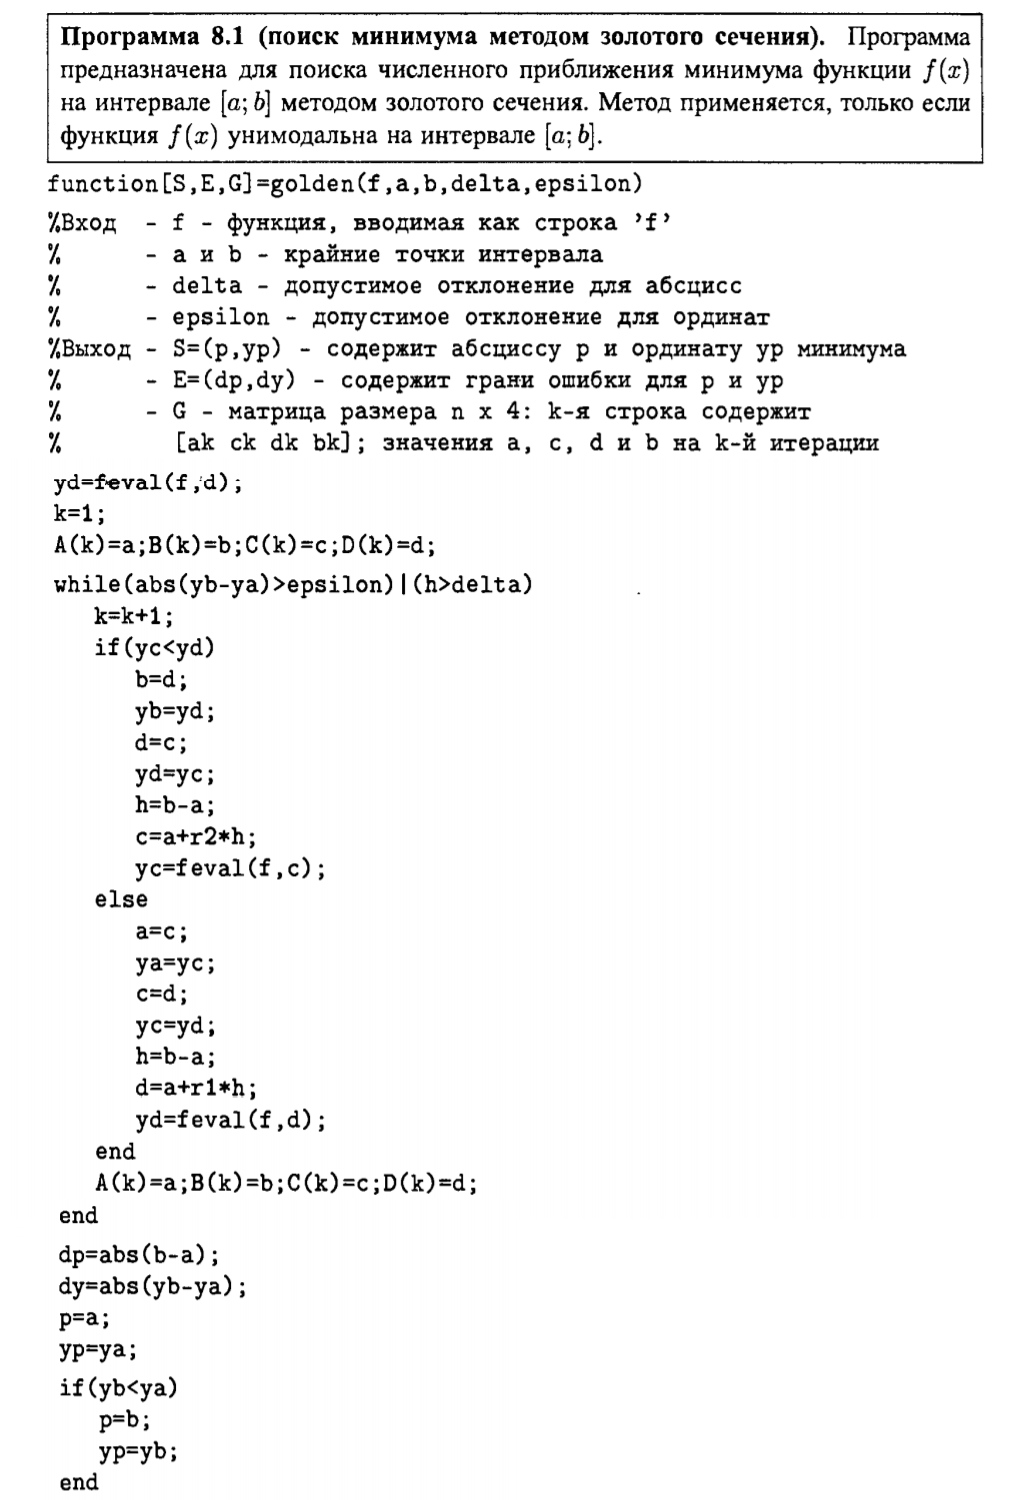

**Упражнение 3**

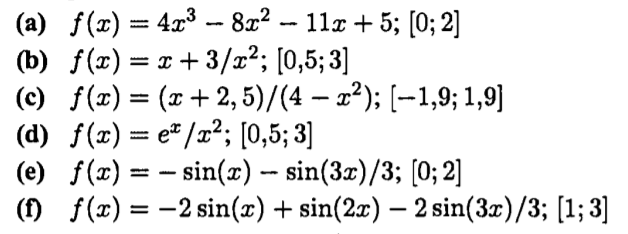

task_size = 7;
f = cell(task_size,1);
lbounds = zeros(task_size,1);
rbounds = zeros(task_size,1);

fnames = ["4*x^3 - 8*x^2 -11*x + 5", ...
    "x + 3/(x^2)", ...
    "(x+2.5)/(4-x^2)", ...
    "exp(x)/x^2", ...
    "-sin(x)-sin(3*x)/3", ...
    "-2*sin(x)+sin(2*x)-2*sin(3*x)/3",...
    "x*sin(2*x)"];

syms x
f{1} = matlabFunction(4*x.^3 - 8*x.^2 -11*x + 5);
lbounds(1) = 0;
rbounds(1) = 2;

f{2} = matlabFunction(x + 3/(x.^2));
lbounds(2) = 0.5;
rbounds(2) = 3;

f{3}  = matlabFunction((x+2.5)/(4-x.^2));
lbounds(3) = -1.9;
rbounds(3) = 1.9;

f{4}  = matlabFunction(exp(x)/x.^2);
lbounds(4) =  0.5;
rbounds(4) = 3;

f{5}  = matlabFunction(-sin(x)-sin(3*x)/3);
lbounds(5) = 0;
rbounds(5) = 2;

f{6}  = matlabFunction(-2*sin(x)+sin(2*x)-2*sin(3*x)/3);
lbounds(6) = 1;
rbounds(6) = 3;

f{7}  = matlabFunction(x*sin(2*x));
lbounds(7) = 0;
rbounds(7) = 6;

Зададим настройки точности выполнения алгоритма

delta=10^(-9);
epsilon=10^(-9);

precision = 8;  
digits(precision);

Запустим цикл по всем функциям из задания

for i=1:task_size
    a = lbounds(i);
    b = rbounds(i);
    minxy = golden(f{i}, a, b, delta, epsilon);
    
    disp("Минимальное значение функции ");
    displayFormula(func2str(f{i}));
    fprintf('на отрезке от %g до %g равно %f и достигается в точке x = %f', a, b, minxy(2), minxy(1));

На графиках видно, что в указанных точках действительно достигается минимум

Минимальное значение функции 


$$-11.0\,x-8.0\,x^{2}+4.0\,x^{3}+5.0$$

на отрезке от 0 до 2 равно -17.407407 и достигается в точке x = 1.833333

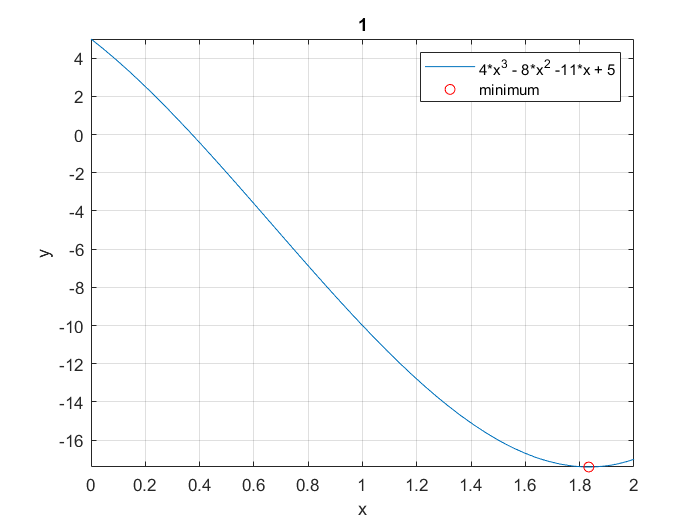

Минимальное значение функции 


$$x+\frac{3.0}{x^{2}}$$

на отрезке от 0.5 до 3 равно 2.725681 и достигается в точке x = 1.817121

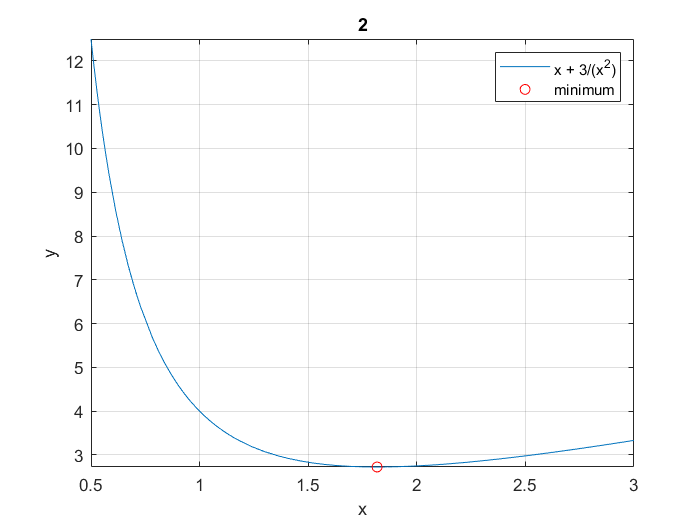

Минимальное значение функции 


$$-\frac{x+2.5}{x^{2}-4.0}$$

на отрезке от -1.9 до 1.9 равно 0.500000 и достигается в точке x = -1.000000

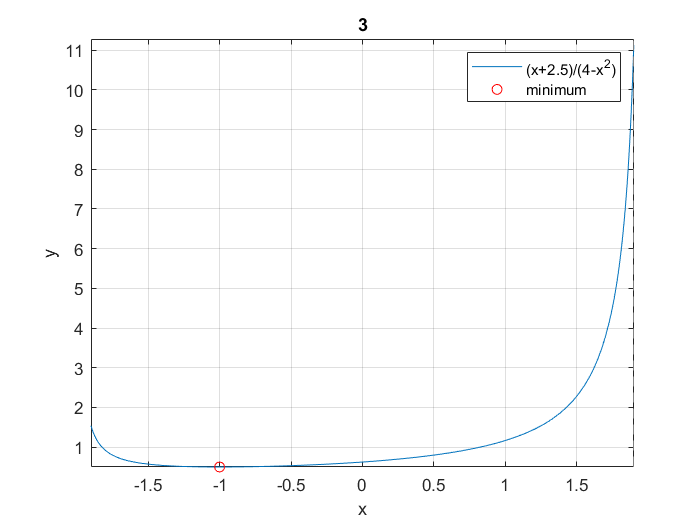

Минимальное значение функции 


$$\frac{1.0\,{\mathrm{e}}^{x}}{x^{2}}$$

на отрезке от 0.5 до 3 равно 1.847264 и достигается в точке x = 2.000000

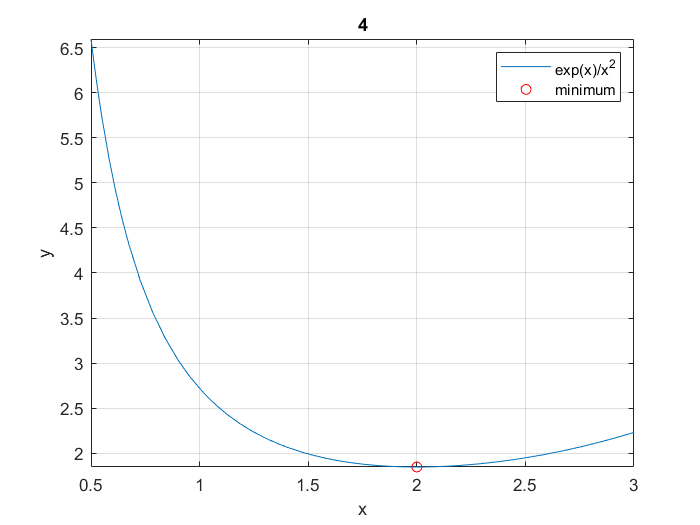

Минимальное значение функции 


$$-0.33333333\,\sin\left(3.0\,x\right)-\sin\left(x\right)$$

на отрезке от 0 до 2 равно -0.942809 и достигается в точке x = 0.785398

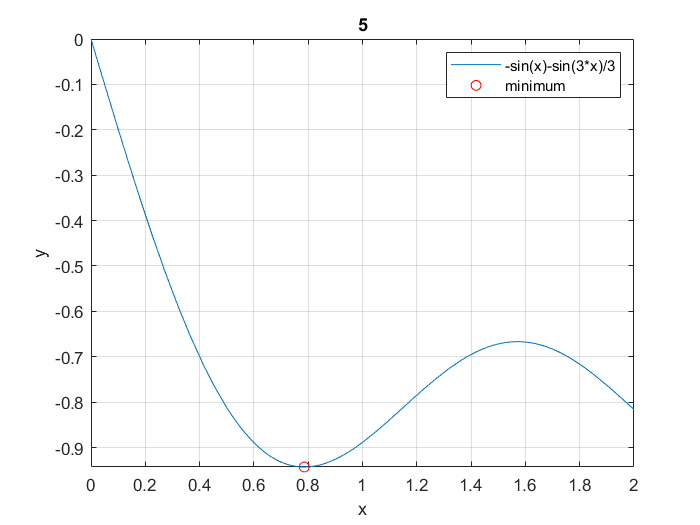

Минимальное значение функции 


$$\sin\left(2.0\,x\right)-0.66666667\,\sin\left(3.0\,x\right)-2.0\,\sin\left(x\right)$$

на отрезке от 1 до 3 равно -2.885618 и достигается в точке x = 2.356194

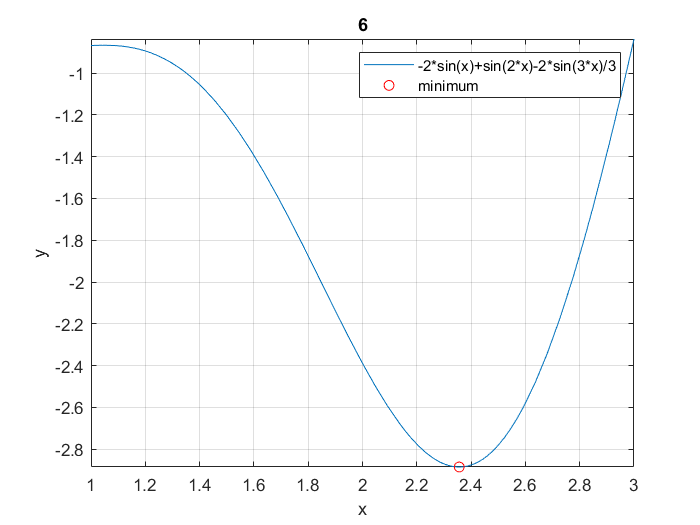

Минимальное значение функции 


$$x\,\sin\left(2.0\,x\right)$$

на отрезке от 0 до 6 равно -2.407235 и достигается в точке x = 2.456590

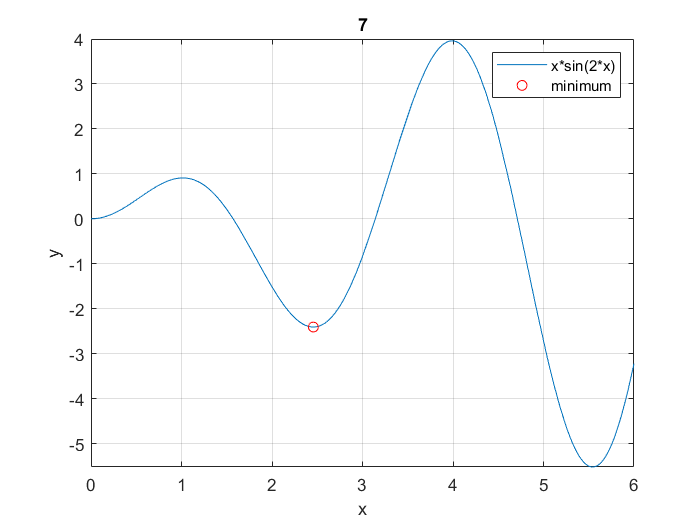

    figure(i)
    fplot(f{i},[a b]);
    title(i)
    grid on
    hold on
    scatter(minxy(1), minxy(2),'r')
    xlabel('x');
    ylabel('y');
    hold off
    legend(fnames(i), "minimum")
end

Видно, что на промежутке от 0 до 6 алгоритм поиска методом золотого сечения обнаружил локальный минимум, а не глобальный. Это связано с тем, что функция $\textrm{xsin}\left(2x\right)$не унимодальна на данном отрезке

## Приложение

#### Определение функции, осуществляющей алгоритмы поиска минимума методом золотого сечения

function[S,E,G]=golden(f, a, b, delta, epsilon)

%Вход   - f         - функция
%       - a и b     - крайние точки интервала
%       - delta     - допустимое отклонение для абсцисс
%       - epsilon   - допустимое отклонение для ординат
%Выход  - S=(p,yp)  - содержит абсциссу p и ординату yp минимума
%       - E=(dp,dy) - содержит грани для ошибки p и yp
%       -  G        - матрица размера n x 4: k-я строка содержит
%          [ak ck dk bk]; значения a, b, c и d на k-й итерации
r1=(sqrt(5)-1)/2;
r2=r1^2;
h=b-a;

ya=f(a);
yb=f(b);
c= a+r2*h;
d= a+r1*h;
yc=f(c);
yd=f(d);

k=1;
A(k)=a;B(k)=b;C(k)=c;D(k)=d;

while (abs(yb-ya)>epsilon)|(h>delta)
    k=k+1;
    if (yc<yd)
        b=d;
        yb=yd;
        d=c;
        yd=yc;
        h=b-a;
        c=a+r2*h;
        yc=f(c);
    else
        a=c;
        ya=yc;
        c=d;
        yc=yd;
        h=b-a;
        d=a+r1*h;
        yd=f(d);
    end
    A(k)=a;B(k)=b;C(k)=c;D(k)=d;
end

dp=abs(b-a);
dy=abs(yb-ya);
p=vpa(a);
yp=vpa(ya);
if(yb<ya)
    p=b;
    yp=yb;
end
G=[A', C', D', B'];
S=[p, yp];
E=[dp, dy];
end